## P2 机器人控制中的典型数学问题求解

## 2.1 线性代数问题

### 2.1.1 矩阵的基本分析

矩阵的基本分析不是只计算一个数，而是从可逆性、秩、迹、大小、病态程度和特征值等方面描述矩阵。det 可用于判断方阵是否接近奇异，但行列式的大小会随矩阵缩放而改变，不能单独代表数值可靠性；cond 或 rcond 更适合评价病态性。

- 矩阵的行列式：det 函数

% 创建一个 3×3 的方阵 A 并计算 A 的行列式
A = [1 -2 4; -5 2 0; 1 0 3];
d1 = det(A)

d1 = -32

A = eye(10)*0.0001;
d2 = det(A)

d2 = 1.0000e-40

设矩阵$A=\left[\matrix{1 & -2 & 4 \cr -5 & 2 & 0 \cr 1 & 0 & 3}\right]$

矩阵的行列式可以判断方阵是否可逆：

- $\(\det(A)\neq 0\)$：矩阵可逆；

- $\(\det(A)=0\)$：矩阵奇异，不可逆；

- 行列式很小不一定说明矩阵病态，还需要结合 `cond` 判断。

矩阵的秩表示矩阵中线性无关行或列的最大数量。对于$ \(n\times n\) $方阵，若 `rank(A)=n`，说明矩阵满秩。

矩阵的迹是主对角线元素之和：$\[{trace}(A)=a_{11}+a_{22}+\cdots+a_{nn} \]$

% 1. 计算教材矩阵的基本特征量
A = [1,-2,4; -5,2,0; 1,0,3];

% 计算矩阵的基本特征量
P2_detA = det(A);              % 行列式
P2_rankA = rank(A);            % 秩
P2_traceA = trace(A);          % 迹
P2_eigA = eig(A);              % 特征值

disp('矩阵 A：')

矩阵 A：


disp(A)

     1    -2     4
    -5     2     0
     1     0     3




disp('矩阵行列式 det(A)：')

矩阵行列式 det(A)：


disp(P2_detA)

   -32




disp('矩阵秩 rank(A)：')

矩阵秩 rank(A)：


disp(P2_rankA)

     3




disp('矩阵迹 trace(A)：')

矩阵迹 trace(A)：


disp(P2_traceA)

     6




disp('矩阵的特征值：')

矩阵的特征值：


disp(P2_eigA)

   -2.1710
    5.4826
    2.6884



### 2.1.2 矩阵的分解

**奇异值分解 SVD（Singular Value Decomposition）**

基础定义

任意 $m\times m$ 矩阵 $A$，都可以做奇异值分解：


$$A_{m\times n} = U_{m\times m} \Sigma_{m \times n} V_{n \times n}^\top$$


- $U$：左奇异向量，m 阶正交矩阵，列向量为 $AA^\top$ 的特征向量

- $V$：右奇异向量，n 阶正交矩阵，列向量为 $A^\top A$的特征向量

- $\Sigma$：奇异值对角矩阵，对角元为**奇异值 **$\sigma_1 \geq \sigma_2 \geq \ldots \geq 0$，其余为 0

关系：$\sigma_i = \sqrt{\lambda_i (A^\top A)}$，奇异值恒非负。

把矩阵 $A$ 看作线性变换：

- $V^\top$：对输入空间做正交旋转

- $\Sigma$：沿各个主轴做缩放，缩放倍数就是奇异值

- $U$：再对输出空间做正交旋转

奇异值大小代表该方向变换的 “作用强度”；奇异值趋近于 0，该方向变换能力几乎丧失。

% 构造一般方阵
% A = [1 3 1 2; 5 6 3 4; 3 3 1 5];

A = randn(3,4);

[U,S,V] = svd(A);


% 显示 SVD 的奇异值
disp('SVD 的奇异值：')

SVD 的奇异值：


disp(S)

    3.4733         0         0         0
         0    2.0322         0         0
         0         0    0.9083         0




S1 = S;
S1(end,:) = 0;

A1 = U*S1*V';
disp(A)

    1.5354    0.8018    0.6126    2.6805
    0.9910   -0.7582   -0.5523    1.1269
    1.5209   -0.4108   -0.7244   -0.5653



disp(A1)

    1.4098    0.6109    0.5349    2.8002
    1.3337   -0.2371   -0.3402    0.8001
    1.3065   -0.7368   -0.8571   -0.3609



换言之，**通过保留最大的几个奇异值，可以实现矩阵信息的有效压缩而不丢失重要特征**，这在图像压缩、特征提取、姿态估计等方面有所应用。

### 2.1.3 矩阵指数 $e^A$ 和指数函数 $e^{At}$

矩阵指数 $e^A$ 不能用逐元素指数 exp(A) 代替。exp(A)表示对矩阵的每个元素分别求指数，而expm(A) 表示按矩阵乘法定义计算$e^A$ 

% 定义连续时间系统矩阵
A = [-1 2; -3 -4];

% 计算矩阵指数
expA = expm(A);

% 计算 t=0.5 时刻的状态转移矩阵
t = 0.5;
Phi = expm(A*t);

% 给定初始状态
x0 = [1;-1];

% 计算 t=0.5 时刻的状态
xt = Phi*x0;

% 对比逐元素指数
eA = exp(A);

disp('矩阵指数 expm(A)：')

矩阵指数 expm(A)：


disp(expA)

    0.0300    0.0792
   -0.1188   -0.0887




disp('状态转移矩阵 Phi(t)：')

状态转移矩阵 Phi(t)：


disp(Phi)

    0.3452    0.2438
   -0.3657   -0.0205




disp('初始状态 x(0)：')

初始状态 x(0)：


disp(x0)

     1
    -1




disp('状态 x(0.5)：')

状态 x(0.5)：


disp(xt)

    0.1014
   -0.3452




disp('逐元素计算 exp(A)：')

逐元素计算 exp(A)：


disp(eA)

    0.3679    7.3891
    0.0498    0.0183



### 2.1.4 雅可比矩阵

给定一个向量值函数，


$$y = f(q), \quad q \in \mathbb{R}^n, y \in \mathbb{R}^m$$


该函数的雅可比矩阵是，


$$J
=
\frac{\partial f}{\partial q}
=
\left[
\begin{array}{cccc}
\frac{\partial f_1}{\partial q_1} & \frac{\partial f_1}{\partial q_2} & \dots & \frac{\partial f_1}{\partial q_n}\\
\frac{\partial f_2}{\partial q_1} & \frac{\partial f_2}{\partial q_2} & \dots & \frac{\partial f_2}{\partial q_n}\\
\vdots & \vdots & \ddots & \vdots\\
\frac{\partial f_m}{\partial q_1} & \frac{\partial f_m}{\partial q_2} & \dots & \frac{\partial f_m}{\partial q_n}
\end{array}
\right]$$


雅可比矩阵在机器人运动学和动力学中扮演重要角色

计算n =  m = 3的一个例子

clear
% 创建一个 3x1 符号向量 q
q = sym("q",[3 1])

$$q = \left(\begin{array}{c} q_{1}\\ q_{2}\\ q_{3} \end{array}\right)$$


f = [q(3)*cos(q(1))*sin(q(2)); q(3)*sin(q(1))*cos(q(2)); q(3)*cos(q(2)) ]

$$f = \left(\begin{array}{c} q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ q_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$


% 求雅各比矩阵

J = jacobian(f,q)

$$J = \left(\begin{array}{ccc} -q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -q_{3}\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right) \end{array}\right)$$

## 2.2 常微分方程问题

- 连续控制系统数学模型的理论基础是微分方程，研究微分方程对其仿真分析有意义 

- 只有少数微分方程（线性定常或极少量非线性方程）有解析解，其他的微分方程得借助数值方法求解  

### 2.2.1 一阶常微分方程数值解

一阶常微分方程组由下式给出


$$\dot{y}_i (t) = f_i (t,y(t)), \quad  i = 1,2,\ldots,n$$


其中$y(t) = [y_1(t),y_2(t),\ldots,y_3(t)]$是系统的状态向量

**简述**

常微分方程（OED）数值解算法 

- Runge–Kutta法、 Adams法、 Gear法等 

- 定步长方法 、变步长方法

- 选定求解器

- 术语“刚度”无法精确定义，但一般而言，当问题的某个位置存在标度差异时，就会出现刚度。例如，如果 ODE 包含的两个解分量在时间尺度上差异极大，则该方程可能是刚性方程。

- 隐式 ODE 不能重写为显式形式，例如 $f(t,x,\dot{x}) = 0$

**Runge–Kutta法和ode45**

**RK法是单步数值积分算法**：计算下一个时刻 $y_{n+1}$，只依赖上一步 $y_n$，不需要历史多步数据，时间步长为$h = t_{n+1}-t_n$，

$s$阶显式 Runge–Kutta 格式定义为


$$k_1 = f(t_n,\,y_n),\\
 k_2 = f\big(t_n + c_2 h,\; y_n + h\,a_{21} k_1\big),\\
k_3 = f\big(t_n + c_3 h,\; y_n + h\big(a_{31}k_1 + a_{32}k_2\big)\big),\\
\vdots\\
k_s = f\Big(t_n + c_s h,\; y_n + h\sum_{j=1}^{s-1} a_{sj}k_j\Big),\\
y_{n+1} = y_n + h\sum_{i=1}^{s} b_i k_i.
$$


对应的 Butcher 表：


$$\[
\begin{array}{c|cccc}
c_1 & & & & \\
c_2 & a_{21} & & & \\
c_3 & a_{31} & a_{32} & & \\
\vdots & \vdots & \vdots & \ddots & \\
c_s & a_{s1} & a_{s2} & \dots & a_{s,s-1}\\
\hline
& b_1 & b_2 & \dots & b_s
\end{array}
\]$$


`ode45` 是**变步长 Runge‑Kutta‑Fehlberg（RKF45）**，同时做 4 阶与 5 阶估计，自动调整步长，在机械臂动力学仿真中最为常用

#### Rössler 方程示例

Rössler 方程为：$\[ \begin{cases} \dot{x}_1=-x_2-x_3\\ \dot{x}_2=x_1+0.2x_2\\ \dot{x}_3=0.2+(x_1-5.7)x_3 \end{cases} \]$

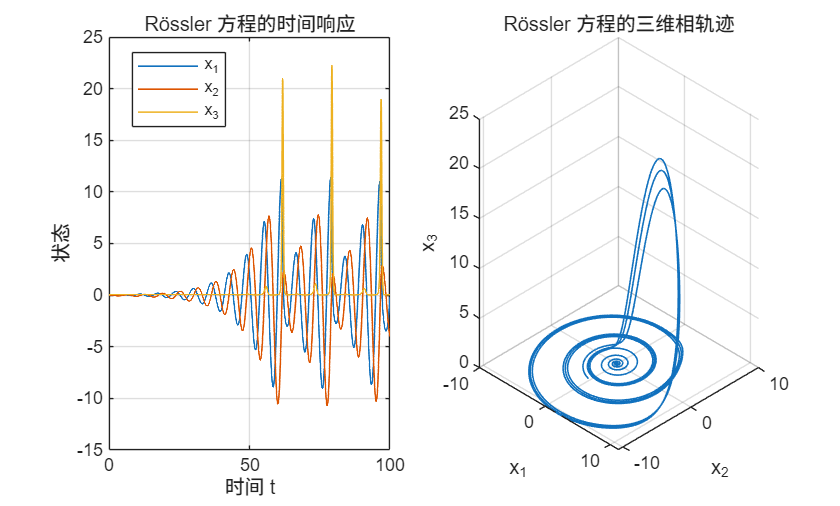

% 定义 Rössler 一阶常微分方程组
f_rossler = @(t,x) [-x(2)-x(3); x(1)+0.2*x(2); 0.2+(x(1)-5.7)*x(3)];

% 设置相对误差和绝对误差
% |e(i)| <= max(RelTol*abs(y(i)),AbsTol(i))
odeOptions = odeset('RelTol',1e-7,'AbsTol',1e-9);

% 设置时间区间和初始状态
tspan = [0,100];
x0 = [0;0;0];

% 使用 ode45 求解
[t,x] = ode45(f_rossler,tspan,x0,odeOptions);

% 创建图形窗口
figure('Color','w')

% 绘制状态变量随时间变化的曲线
subplot(1,2,1)
plot(t,x,'LineWidth',0.8)
grid on
xlabel('时间 t')
ylabel('状态')
title('Rössler 方程的时间响应')
legend('x_1','x_2','x_3','Location','best')

% 绘制三维相轨迹
subplot(1,2,2)
plot3(x(:,1),x(:,2),x(:,3),'LineWidth',0.8)
grid on
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
title('Rössler 方程的三维相轨迹')
view(45,25)

变量说明：

- `t`：求解器返回的时间点；

- `x`：每个时间点对应的状态值；

- `x(:,1)`：第一个状态变量；

- `x(:,2)`：第二个状态变量；

- `x(:,3)`：第三个状态变量。

#### **带参数的微分方程**

当微分方程含有模型参数时，可以用匿名函数闭包传递参数。

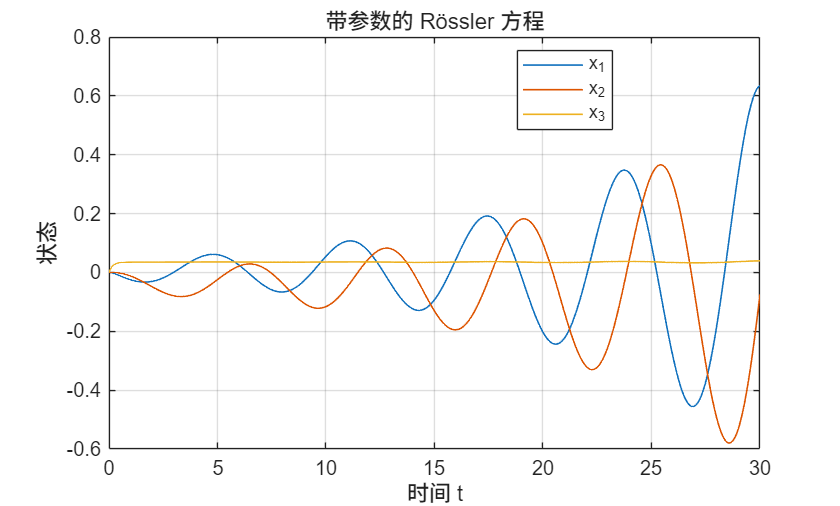

% 设置模型参数
theta = [0.2,0.2,5.7];

% 使用匿名函数传递模型参数
f_rosslerParameter = @(t,x) [-x(2)-x(3); x(1)+theta(1)*x(2); theta(2)+(x(1)-theta(3))*x(3)];

% 使用 ode45 求解
[t,x] = ode45(f_rosslerParameter,[0,30],[0;0;0],odeOptions);

% 绘制带参数的 Rössler 方程响应
figure('Color','w')
plot(t,x,'LineWidth',0.8)
grid on
xlabel('时间 t')
ylabel('状态')
title('带参数的 Rössler 方程')
legend('x_1','x_2','x_3','Location','best')

### 2.2.2 常微分方程的转换

考虑二阶 Van der Pol 方程：$\[ y''-(1-y^2)y'+y=0 \]$

令：$\[ x_1=y,\qquad x_2=y' \]$

则：$\[ \dot{x}_1=x_2 \]\[ \dot{x}_2=(1-x_1^2)x_2-x_1 \]$

因此：$\dot{x}=\left[\matrix{x_2 \cr (1-x_1^2)x_2-x_1}\right]$

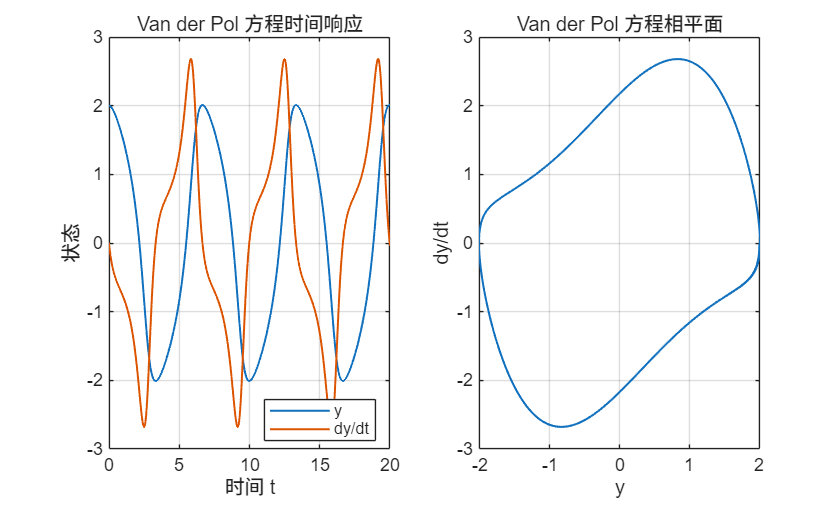

% 将二阶 Van der Pol 方程转换成一阶状态方程组
f_vdp = @(t,x) [x(2); (1-x(1)^2)*x(2)-x(1)];

% 设置初始条件
x0 = [2;0];

% 使用 ode45 求解
[t,x] = ode45(f_vdp,[0,20],x0,odeOptions);

% 绘制时间响应和相平面轨迹
figure('Color','w')

% 时间响应
subplot(1,2,1)
plot(t,x,'LineWidth',1)
grid on
xlabel('时间 t')
ylabel('状态')
title('Van der Pol 方程时间响应')
legend('y','dy/dt','Location','best')

% 相平面轨迹
subplot(1,2,2)
plot(x(:,1),x(:,2),'LineWidth',1)
grid on
xlabel('y')
ylabel('dy/dt')
title('Van der Pol 方程相平面')

### 2.2.3 微分方程数值解的验证

数值解需要通过误差比较、残差计算或解析解对照进行验证。

考虑：$\[ x'=-2x+\sin(t),\qquad x(0)=0 \]$

分别使用宽松和严格的误差容限求解。

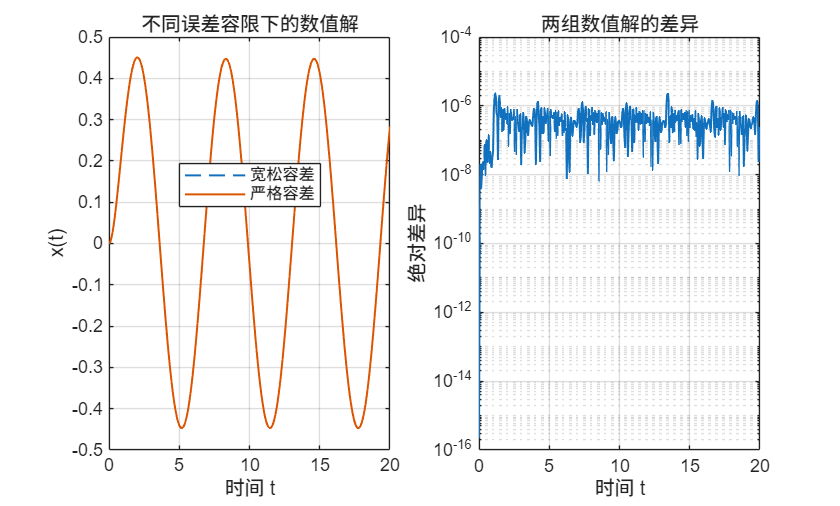

% 定义一阶微分方程
f_decay = @(t,x) -2*x + sin(t);

% 设置统一的时间输出网格
tGrid = linspace(0,20,401);

% 设置宽松误差容限
looseOptions = odeset('RelTol',1e-5,'AbsTol',1e-7);

% 设置严格误差容限
tightOptions = odeset('RelTol',1e-9,'AbsTol',1e-11);

% 使用宽松容限求解
[~,xLoose] = ode45(f_decay,tGrid,0,looseOptions);

% 使用严格容限求解
[~,xTight] = ode45(f_decay,tGrid,0,tightOptions);

% 计算两次结果的绝对差异
x_difference = abs(xLoose - xTight);

% 计算最大差异
x_maxDifference = max(x_difference);

% 检查初始条件
x_initialResidual = abs(xTight(1));

% 创建图形窗口
figure('Color','w')

% 绘制两组数值解
subplot(1,2,1)
plot(tGrid,xLoose,'--','LineWidth',1)
hold on
plot(tGrid,xTight,'-','LineWidth',1)
grid on
xlabel('时间 t')
ylabel('x(t)')
title('不同误差容限下的数值解')
legend('宽松容差','严格容差','Location','best')

% 绘制两组解的差异
subplot(1,2,2)
semilogy(tGrid,x_difference + eps,'LineWidth',1)
grid on
xlabel('时间 t')
ylabel('绝对差异')
title('两组数值解的差异')


% 显示计算结果
disp('宽松与严格容差的最大差异：')

宽松与严格容差的最大差异：


disp(x_maxDifference)

   2.3072e-06




disp('初始条件残差：')

初始条件残差：


disp(x_initialResidual)

     0




disp('输出时间点数量：')

输出时间点数量：


disp([size(xLoose,1),size(xTight,1)])

   401   401



如果两组结果的最大差异很小，说明数值解对误差容限设置不敏感。

### 2.2.4 线性常微分方程的解析求解

对于部分线性常微分方程，可以使用 `dsolve` 求解析解。

考虑：$\[ y''+3y'+2y=e^{-t} \]$

初始条件为：$\[ y(0)=1,\qquad y'(0)=0 \]$

% 定义符号变量
syms y(t)

% 定义二阶线性常微分方程
ode_obj = diff(y,t,2)+3*diff(y,t)+2*y==exp(-t);

% 求解析解
y_solution = simplify(dsolve(ode_obj,y(0)==1,subs(diff(y,t),t,0)==0));

disp('线性微分方程的解析解：')

线性微分方程的解析解：


disp(y_solution)

$${\mathrm{e}}^{-t}\,\left(t+1\right)$$

解析解为：$\[ y(t)=e^{-t}(t+1) \]$

将同一方程转换成一阶状态方程：


$$\[ \begin{cases} x_1'=x_2\\ x_2'=e^{-t}-3x_2-2x_1 \end{cases} \]$$


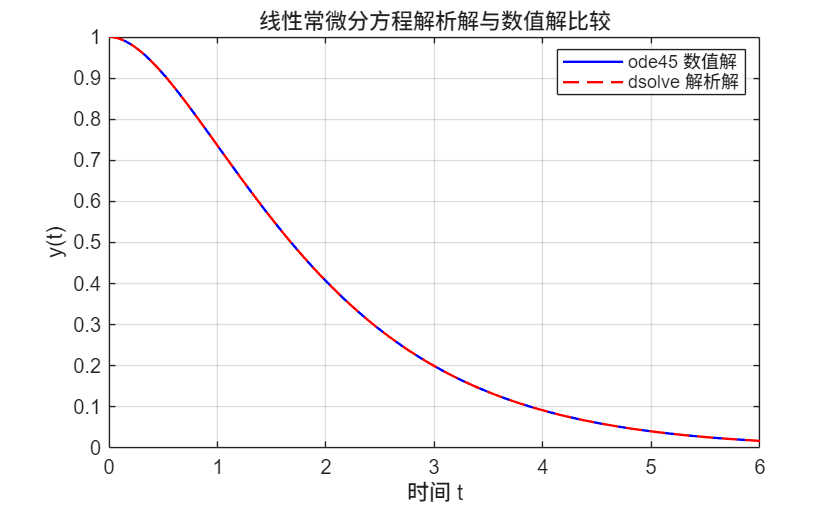

% 将二阶方程转换为一阶状态方程
f_ode = @(t,x) [x(2); exp(-t)-3*x(2)-2*x(1)];

% 使用 ode45 求数值解
[ts,x] = ode45(f_ode,[0,6],[1;0],odeOptions);

% 计算解析解
x_analytic = exp(-ts).*(ts+1);

% 计算解析解和数值解的最大误差
x_err = max(abs(x(:,1)-x_analytic));

% 绘制解析解与数值解
figure('Color','w')
plot(ts,x(:,1),'b-','LineWidth',1.2)
hold on
plot(ts,x_analytic,'r--','LineWidth',1.2)
grid on
xlabel('时间 t')
ylabel('y(t)')
title('线性常微分方程解析解与数值解比较')
legend('ode45 数值解','dsolve 解析解','Location','best')


disp('解析解与数值解的最大误差：')

解析解与数值解的最大误差：


disp(x_err)

   2.7005e-09



以将解析解代回原微分方程进行验证：

% 验证解析解是否满足原微分方程
equationResidual = simplify(subs(diff(y,t,2) + 3*diff(y,t) + 2*y - exp(-t),y,y_solution));

% 显示残差
disp('解析解代回原微分方程后的残差：')

解析解代回原微分方程后的残差：


disp(equationResidual)

$$0$$

残差为0，说明解析解严格满足原微分方程。

## 2.3 代数方程的MATLAB求解*

代数方程的求解主要包括：

- 线性方程；

- 一般非线性方程；

- 非线性矩阵方程。

无论采用哪种方法，求解后都应进行验证：$r=F\left(x\right)$

如果残差$r$接近 0，说明数值解基本满足原方程。

### 2.3.1 线性方程求解问题及MATLAB实现

线性方程组通常写成：$\[ Ax=b \]$

MATLAB 中最常用的求解方式是：x = A\b;

对于 $n$个未知量，线性方程组有三种情况：

- 唯一解：$\({rank}(A)={rank}([A,b])=n\)$

- 无穷多解：$\({rank}(A)={rank}([A,b])<n\)$

- 无解：$\({rank}(A)\neq{rank}([A,b])\)$

#### 唯一解

% 构造一个有唯一解的线性方程组
P2_22_Aunique = [4,1;
                  2,3];

P2_22_bunique = [9;
                  13];

% 使用左除求解
P2_22_xunique = P2_22_Aunique\P2_22_bunique;

% 计算残差
P2_22_resUnique = norm(P2_22_Aunique*P2_22_xunique-P2_22_bunique);

disp('唯一解：')

唯一解：


disp(P2_22_xunique)

    1.4000
    3.4000




disp('左除法残差：')

左除法残差：


disp(P2_22_resUnique)

     0



#### 无穷多解

% 构造一个秩亏的线性方程组
P2_22_Aunder = [1,2,3;
                  2,4,6];

P2_22_bunder = [3;6];

% 求一个特解
P2_22_xParticular = pinv(P2_22_Aunder)*P2_22_bunder;

% 求齐次方程 A*x=0 的基础解系
P2_22_nullBasis = null(P2_22_Aunder);

% 构造一个通解
P2_22_xGeneral = P2_22_xParticular + P2_22_nullBasis*[0.5;-0.2];

% 计算通解残差
P2_22_resInfinite = norm(P2_22_Aunder*P2_22_xGeneral-P2_22_bunder);

% 计算系数矩阵和增广矩阵的秩
P2_22_rankA = rank(P2_22_Aunder);
P2_22_rankAugmented = rank( ...
    [P2_22_Aunder,P2_22_bunder]);

% 对增广矩阵进行行最简形变换
[P2_22_rrefResult,P2_22_pivotColumns] = rref([P2_22_Aunder,P2_22_bunder]);

disp('一个特解：')

一个特解：


disp(P2_22_xParticular)

    0.2143
    0.4286
    0.6429




disp('齐次方程的基础解系：')

齐次方程的基础解系：


disp(P2_22_nullBasis)

    0.9514   -0.1530
   -0.2784   -0.7980
   -0.1315    0.5830




disp('一个通解：')

一个通解：


disp(P2_22_xGeneral)

    0.7206
    0.4489
    0.4605




disp('通解残差：')

通解残差：


disp(P2_22_resInfinite)

   1.9860e-15




disp('rank(A) 与 rank([A,b])：')

rank(A) 与 rank([A,b])：


disp([P2_22_rankA,P2_22_rankAugmented])

     1     1




disp('增广矩阵的行最简形：')

增广矩阵的行最简形：


disp(P2_22_rrefResult)

     1     2     3     3
     0     0     0     0




disp('主元列：')

主元列：


disp(P2_22_pivotColumns)

     1



对于无穷多解，`pinv(A)*b` 给出的是一个特解；`null(A)` 给出齐次方程的解空间方向。

通解可以表示为：$\[ x=x_p+N\alpha \]$

其中：

- $\(x_p\) $是一个特解；

- $N$是 `null(A)` 返回的零空间基；

- $\(\alpha\) $是任意参数。

#### 无解方程

% 构造一个无解方程组
P2_22_Ainconsistent = [1,1;
                        2,2];

P2_22_binconsistent = [1;
                        3];

% 用 pinv 求最小二乘意义下的近似解
P2_22_xLeastSquares = ...
    pinv(P2_22_Ainconsistent)*P2_22_binconsistent;

% 计算最小二乘残差
P2_22_resInconsistent = norm( ...
    P2_22_Ainconsistent*P2_22_xLeastSquares ...
    - P2_22_binconsistent);

% 判断系数矩阵和增广矩阵的秩
P2_22_rankAInconsistent = ...
    rank(P2_22_Ainconsistent);

P2_22_rankAugInconsistent = ...
    rank([P2_22_Ainconsistent,P2_22_binconsistent]);

disp('最小二乘近似解：')

最小二乘近似解：


disp(P2_22_xLeastSquares)

    0.7000
    0.7000




disp('最小二乘残差：')

最小二乘残差：


disp(P2_22_resInconsistent)

    0.4472




disp('rank(A) 与 rank([A,b])：')

rank(A) 与 rank([A,b])：


disp([P2_22_rankAInconsistent, ...
      P2_22_rankAugInconsistent])

     1     2



如果：

`rank(A) ~= rank([A,b])`

说明方程组无精确解。此时 `pinv` 给出的是最小二乘解，而不是严格意义下的精确解。

#### 求解矩阵方程$\(AXB=C\)$

矩阵方程：$\(AXB=C\)$

可以利用向量化公式：$\[ {vec}(AXB) = (B^T\otimes A){vec}(X) \]$

其中$ \(\otimes\) $表示 Kronecker 积，在 MATLAB 中使用 `kron`。

% 已知矩阵 A、B 和 C
A = [1,2;
     0,1];

A1 = [2,0;
     1,3];

C = [9,-3;
     4,0];

% 利用 vec(AXB) = (B^T ⊗ A)vec(X)
K = kron(A1.',A);

% 求解向量化后的 X
vecX = K \ C(:);

% 将列向量还原为矩阵 X
X = reshape(vecX, size(A,2), size(A1,1));

% 计算残差
residual = norm(A*X*A1-C,'fro');

disp('求得的矩阵 X：')

求得的矩阵 X：


disp(X)

     1    -1
     2     0




disp('AXB=C 的残差：')

AXB=C 的残差：


disp(residual)

     0



#### **Lyapunov 方程**

连续 Lyapunov 方程通常写成：$\[ AX+XA^T=-Q\]$

MATLAB 使用：`X = lyap(A,Q);`

% 连续 Lyapunov 方程
P2_22_Alyap = [-1,2;
                -3,-4];

P2_22_Qlyap = eye(2);

% 求解 AX+XA'=-Q
P2_22_Xlyap = lyap(P2_22_Alyap,P2_22_Qlyap);

% 计算残差
P2_22_resLyap = norm(P2_22_Alyap*P2_22_Xlyap + P2_22_Xlyap*P2_22_Alyap' + P2_22_Qlyap,'fro');

disp('连续 Lyapunov 方程的解 X：')

连续 Lyapunov 方程的解 X：


disp(P2_22_Xlyap)

    0.3000   -0.1000
   -0.1000    0.2000




disp('连续 Lyapunov 方程残差：')

连续 Lyapunov 方程残差：


disp(P2_22_resLyap)

   2.4825e-16



**Sylvester 方程**

Sylvester 方程实际上是Lyapunov 方程的推广，又称为广义Lyapunov 方程，常见形式为：

常见形式为：$\[ AX+XB=-C \]$

MATLAB 使用：`X = lyap(A,B,C);`

% 定义矩阵
A = [1,2;
     0,1];

A1 = [2,0;
     1,3];

C = [9,-3;
     4,0];

% 使用 lyap 求解
X_lyap = lyap(A,A1,C);

% 计算残差
res_lyap = norm(A*X_lyap + X_lyap*A1 + C,'fro');

disp('lyap 求得的 X：')

lyap 求得的 X：


disp(X_lyap)

   -2.3611    0.7500
   -1.3333         0




disp('lyap 残差：')

lyap 残差：


disp(res_lyap)

     0



#### Riccati 方程

标准连续代数 Riccati 方程为：$\[ A^TX+XA-XBX+Q=0 \]$

MATLAB 中可以使用 i`care` 求解。

### 2.3.2 一般非线性方程的求解

一般非线性方程可以写成：$\[ f(x)=0 \]$

常用方法包括：

- `solve`：符号求解；

- `fsolve`：求解多变量非线性方程组；

- `fimplicit`：绘制隐函数曲线。

#### 符号求解

% 符号求解一元非线性方程
syms P2_22_xSymbol

P2_22_symbolicRoots = solve( ...
    P2_22_xSymbol^2-5==0, ...
    P2_22_xSymbol);

disp('符号方程 x^2-5=0 的解：')

符号方程 x^2-5=0 的解：


disp(P2_22_symbolicRoots)

$$\left(\begin{array}{c} \sqrt{5}\\ -\sqrt{5} \end{array}\right)$$

#### fsolve 求解非线性方程组

考虑方程组：$\[ \begin{cases} x^2+y^2-1=0\\ x-y=0 \end{cases} \]$

它的解为：$\[ (x,y)=\left(\frac{\sqrt{2}}2,\frac{\sqrt{2}}2\right) \]$

以及：$\[ (x,y)=\left(-\frac{\sqrt{2}}2,-\frac{\sqrt{2}}2\right) \]$

% 定义二元非线性方程组
P2_22_nonlinearFunction = @(u) [u(1)^2 + u(2)^2 - 1; u(1) - u(2)];

% 设置 fsolve 求解选项
P2_22_fsolveOptions = optimoptions('fsolve','Display','off','FunctionTolerance',1e-12);

% 从正初值出发求解
[P2_22_rootPositive,P2_22_fvalPositive,P2_22_flagPositive] = fsolve(P2_22_nonlinearFunction,[0.7;0.7],P2_22_fsolveOptions);

% 从负初值出发求解
[P2_22_rootNegative,P2_22_fvalNegative,P2_22_flagNegative] = fsolve(P2_22_nonlinearFunction,[-0.7;-0.7],P2_22_fsolveOptions);

% 计算两个解的残差
P2_22_resPositive = norm(P2_22_fvalPositive);
P2_22_resNegative = norm(P2_22_fvalNegative);

% 显示正初值得到的解
disp('正初值得到的根：')

正初值得到的根：


disp(P2_22_rootPositive)

    0.7071
    0.7071




% 显示负初值得到的解
disp('负初值得到的根：')

负初值得到的根：


disp(P2_22_rootNegative)

   -0.7071
   -0.7071




% 显示两个解的残差
disp('两个根的残差：')

两个根的残差：


disp([P2_22_resPositive,P2_22_resNegative])

   1.0e-08 *

    0.2604    0.2604




% 显示退出标志
disp('两个求解过程的退出标志：')

两个求解过程的退出标志：


disp([P2_22_flagPositive,P2_22_flagNegative])

     1     1



这个例子说明，`fsolve` 的结果与初始值有关。不同初值可能收敛到不同的根。

#### 非线性方程组的图解法

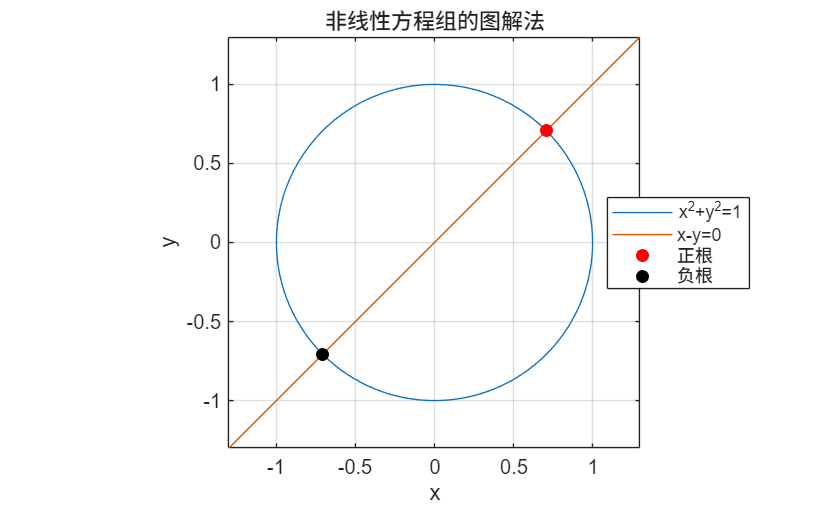

% 绘制两个方程对应的隐函数曲线
figure('Color','w')

% 绘制圆：x^2+y^2=1
P2_22_hCircle = fimplicit(@(x,y) x.^2 + y.^2 - 1,[-1.3,1.3]);

hold on

% 绘制直线：x-y=0
P2_22_hDiagonal = fimplicit(@(x,y) x - y,[-1.3,1.3]);

% 标出正数值解
P2_22_hPositive = plot(P2_22_rootPositive(1),P2_22_rootPositive(2),'ro','MarkerFaceColor','r');

% 标出负数值解
P2_22_hNegative = plot(P2_22_rootNegative(1),P2_22_rootNegative(2),'ko','MarkerFaceColor','k');

% 设置图形属性
grid on
axis equal
xlabel('x')
ylabel('y')
title('非线性方程组的图解法')

% 添加图例
legend([P2_22_hCircle,P2_22_hDiagonal,P2_22_hPositive,P2_22_hNegative],'x^2+y^2=1','x-y=0','正根','负根','Location','best')

图解法适合：

- 观察方程的根大致分布；

- 判断是否存在多个根；

- 为 `fsolve` 选择合适的初值；

- 验证数值求解结果是否合理。

### 2.3.3 非线性矩阵方程的MATLAB求解

`fsolve` 可以求解非线性矩阵方程的一个根。由于非线性矩阵方程可能存在多个解，因此：

- 不同初值可能得到不同的根；

- 只调用一次 `fsolve` 通常只能得到一个解；

- 可以随机产生多个初值，重复调用 `fsolve`；

- 对得到的结果进行去重，就可以搜索多个不同的解。

设非线性矩阵方程为：$F\left(X\right)=0$

其中$X$是未知矩阵，$\(F(X)\) $返回一个与$X$维数相同的矩阵。

**多解搜索函数**

下面的 `more_sols` 函数实现了其基本思想：

- 设置随机初值；

- 调用 `fsolve`；

- 检查求解是否成功；

- 检查残差是否足够小；

- 与已有解比较，删除重复解；

- 在规定时间内继续搜索。

% 固定随机数种子
rng(1)

% 定义第一个方程
P2_223_f1 = @(x,y) x.^2.*exp(-x.*y.^2/2) + exp(-x/2).*sin(x.*y);

% 定义第二个方程
P2_223_f2 = @(x,y) y.^2.*cos(y+x.^2) + x.^2.*exp(x+y);

% 将两个方程组合成 fsolve 所需的向量函数
P2_223_f = @(u) [P2_223_f1(u(1),u(2)); P2_223_f2(u(1),u(2))];

% 设置搜索参数
P2_223_A = 12;
P2_223_tol = 1e-10;
P2_223_tlim = 5;

% 初始化解集合
P2_223_VectorSolutions = zeros(2,1,0);

% 设置 fsolve 选项
P2_223_options = optimoptions('fsolve','Display','off','FunctionTolerance',P2_223_tol,'StepTolerance',P2_223_tol,'MaxIterations',1000,'MaxFunctionEvaluations',5000);

% 开始搜索
P2_223_startTime = tic;
P2_223_M = 0;
P2_223_rootTolerance = 1e-5;

while toc(P2_223_startTime) < P2_223_tlim

    % 在 [-6,6] 范围内产生随机初值
    P2_223_x0 = P2_223_A*(rand(2,1)-0.5);

    % 求解非线性方程组
    [P2_223_x,P2_223_fval,P2_223_exitflag] = fsolve(P2_223_f,P2_223_x0,P2_223_options);

    P2_223_M = P2_223_M + 1;

    % 求解失败时跳过
    if P2_223_exitflag <= 0
        continue
    end

    % 计算残差
    P2_223_residual = norm(P2_223_fval(:),inf);

    if P2_223_residual > max(10*P2_223_tol,1e-8)
        continue
    end

    % 判断是否为新解
    P2_223_isNew = true;

    for P2_223_j = 1:size(P2_223_VectorSolutions,3)
        P2_223_difference = norm(P2_223_VectorSolutions(:,:,P2_223_j)-P2_223_x,'fro');

        if P2_223_difference < P2_223_rootTolerance
            P2_223_isNew = false;
            break
        end
    end

    % 保存新解
    if P2_223_isNew
        if isempty(P2_223_VectorSolutions)
            P2_223_VectorSolutions(:,:,1) = P2_223_x;
        else
            P2_223_VectorSolutions(:,:,end+1) = P2_223_x;
        end

        disp(['找到第 ',num2str(size(P2_223_VectorSolutions,3)),' 个不同的解：'])
        disp(P2_223_x)
        disp(['残差：',num2str(P2_223_residual)])
    end
end

找到第 1 个不同的解：


   -0.7329
    1.5623



残差：4.0434e-13


找到第 2 个不同的解：


   -0.0000
    4.7124



残差：1.2582e-12


找到第 3 个不同的解：


    0.0000
    1.5708



残差：1.6983e-09


找到第 4 个不同的解：


    2.4778
   -2.5387



残差：3.908e-13


找到第 5 个不同的解：


    3.5430
   -4.4335



残差：4.7073e-14


找到第 6 个不同的解：


   -0.0000
   -4.7124



残差：2.3117e-12


找到第 7 个不同的解：


    4.4255
   -4.9692



残差：1.8627e-11


找到第 8 个不同的解：


   -0.0000
   -1.5708



残差：9.9205e-10


找到第 9 个不同的解：


    2.5531
   -4.9221



残差：6.2888e-10


找到第 10 个不同的解：


    0.6168
   -5.0927



残差：9.6408e-10


找到第 11 个不同的解：


    1.1050
   -2.8194



残差：4.6152e-13


找到第 12 个不同的解：


    2.1774
   -2.8864



残差：6.9722e-13


找到第 13 个不同的解：


    1.5618
   -4.0230



残差：5.7437e-09


找到第 14 个不同的解：


    3.1145
   -5.0434



残差：5.3735e-14


找到第 15 个不同的解：


   -0.2748
    4.3938



残差：1.0023e-09


找到第 16 个不同的解：


    4.6012
   -4.7795



残差：6.7502e-14


找到第 17 个不同的解：


    2.7800
   -3.3902



残差：6.1125e-10


找到第 18 个不同的解：


    2.8583
   -6.5947



残差：1.4849e-14


找到第 19 个不同的解：


    2.3703
   -3.9762



残差：2.6759e-11


找到第 20 个不同的解：


    5.8666
   -5.8906



残差：3.7709e-11


找到第 21 个不同的解：


    4.8608
   -6.4631



残差：5.56e-13


找到第 22 个不同的解：


    1.0720
   -5.8613



残差：2.0919e-14


找到第 23 个不同的解：


    3.8035
   -4.1298



残差：6.0396e-14


找到第 24 个不同的解：


    5.2750
   -5.3601



残差：4.2633e-14


找到第 25 个不同的解：


    3.9361
   -4.7890



残差：1.2008e-12


找到第 26 个不同的解：


    3.7168
   -5.9167



残差：7.742e-12


找到第 27 个不同的解：


    4.4679
   -5.6252



残差：9.051e-11


找到第 28 个不同的解：


    2.9678
   -4.2343



残差：1.2834e-13


找到第 29 个不同的解：


    4.0381
   -5.4459



残差：1.0236e-12


找到第 30 个不同的解：


    4.1259
   -6.0915



残差：3.8399e-11


找到第 31 个不同的解：


    1.8648
   -5.0540



残差：6.834e-13


找到第 32 个不同的解：


    4.7101
   -5.3359



残差：1.1324e-10


找到第 33 个不同的解：


    2.1001
   -5.9837



残差：1.3462e-10


找到第 34 个不同的解：


    2.7144
   -5.7869



残差：1.6064e-11


找到第 35 个不同的解：


    5.7960
   -5.9623



残差：2.1316e-14


找到第 36 个不同的解：


    5.1571
   -5.4826



残差：2.025e-13


找到第 37 个不同的解：


    3.6267
   -5.1975



残差：4.1252e-10


找到第 38 个不同的解：


    5.1761
   -6.0694



残差：3.3598e-10


找到第 39 个不同的解：


   -0.0000
   -7.8540



残差：1.0559e-09


找到第 40 个不同的解：


    1.4079
   -6.6943



残差：5.846e-15


找到第 41 个不同的解：


    5.3720
   -5.8481



残差：7.816e-14


找到第 42 个不同的解：


    4.7917
   -5.9007



残差：7.4607e-14


找到第 43 个不同的解：


   -0.0000
    7.8540



残差：1.8886e-14


找到第 44 个不同的解：


    3.2411
   -5.8158



残差：2.6978e-14


找到第 45 个不同的解：


    5.4417
   -6.3505



残差：2.4869e-14


找到第 46 个不同的解：


    2.2957
   -6.8423



残差：3.3245e-10


找到第 47 个不同的解：


   -9.1512
    0.1317



残差：7.7563e-11


找到第 48 个不同的解：


    4.5254
   -6.2480



残差：3.2596e-13


找到第 49 个不同的解：


    3.8051
   -6.6049



残差：1.7764e-15


找到第 50 个不同的解：


    3.3550
   -6.5546



残差：2.0317e-09


找到第 51 个不同的解：


    5.9590
   -6.3264



残差：1.1369e-13


找到第 52 个不同的解：


    5.2152
   -6.6263



残差：2.7267e-13


找到第 53 个不同的解：


   -0.0000
   10.9956



残差：5.1822e-14


找到第 54 个不同的解：


    6.0209
   -6.7831



残差：3.8725e-13


找到第 55 个不同的解：


    5.7974
   -6.5028



残差：8.2423e-12


找到第 56 个不同的解：


    3.1078
   -8.0869



残差：1.7192e-13


找到第 57 个不同的解：


  -10.7978
    0.0523



残差：2.8328e-10


找到第 58 个不同的解：


    3.4599
   -7.2639



残差：3.025e-12


找到第 59 个不同的解：


    4.9232
   -7.0194



残差：2.6468e-13


找到第 60 个不同的解：


    5.5000
   -6.8544



残差：1.0738e-09



% 显示搜索结果
disp(['fsolve 总调用次数：',num2str(P2_223_M)])

fsolve 总调用次数：13455


disp(['找到的不同解数量：',num2str(size(P2_223_VectorSolutions,3))])

找到的不同解数量：60



for P2_223_j = 1:size(P2_223_VectorSolutions,3)
    disp(['第 ',num2str(P2_223_j),' 个解：'])
    disp(P2_223_VectorSolutions(:,:,P2_223_j))
end

第 1 个解：


   -0.7329
    1.5623



第 2 个解：


   -0.0000
    4.7124



第 3 个解：


    0.0000
    1.5708



第 4 个解：


    2.4778
   -2.5387



第 5 个解：


    3.5430
   -4.4335



第 6 个解：


   -0.0000
   -4.7124



第 7 个解：


    4.4255
   -4.9692



第 8 个解：


   -0.0000
   -1.5708



第 9 个解：


    2.5531
   -4.9221



第 10 个解：


    0.6168
   -5.0927



第 11 个解：


    1.1050
   -2.8194



第 12 个解：


    2.1774
   -2.8864



第 13 个解：


    1.5618
   -4.0230



第 14 个解：


    3.1145
   -5.0434



第 15 个解：


   -0.2748
    4.3938



第 16 个解：


    4.6012
   -4.7795



第 17 个解：


    2.7800
   -3.3902



第 18 个解：


    2.8583
   -6.5947



第 19 个解：


    2.3703
   -3.9762



第 20 个解：


    5.8666
   -5.8906



第 21 个解：


    4.8608
   -6.4631



第 22 个解：


    1.0720
   -5.8613



第 23 个解：


    3.8035
   -4.1298



第 24 个解：


    5.2750
   -5.3601



第 25 个解：


    3.9361
   -4.7890



第 26 个解：


    3.7168
   -5.9167



第 27 个解：


    4.4679
   -5.6252



第 28 个解：


    2.9678
   -4.2343



第 29 个解：


    4.0381
   -5.4459



第 30 个解：


    4.1259
   -6.0915



第 31 个解：


    1.8648
   -5.0540



第 32 个解：


    4.7101
   -5.3359



第 33 个解：


    2.1001
   -5.9837



第 34 个解：


    2.7144
   -5.7869



第 35 个解：


    5.7960
   -5.9623



第 36 个解：


    5.1571
   -5.4826



第 37 个解：


    3.6267
   -5.1975



第 38 个解：


    5.1761
   -6.0694



第 39 个解：


   -0.0000
   -7.8540



第 40 个解：


    1.4079
   -6.6943



第 41 个解：


    5.3720
   -5.8481



第 42 个解：


    4.7917
   -5.9007



第 43 个解：


   -0.0000
    7.8540



第 44 个解：


    3.2411
   -5.8158



第 45 个解：


    5.4417
   -6.3505



第 46 个解：


    2.2957
   -6.8423



第 47 个解：


   -9.1512
    0.1317



第 48 个解：


    4.5254
   -6.2480



第 49 个解：


    3.8051
   -6.6049



第 50 个解：


    3.3550
   -6.5546



第 51 个解：


    5.9590
   -6.3264



第 52 个解：


    5.2152
   -6.6263



第 53 个解：


   -0.0000
   10.9956



第 54 个解：


    6.0209
   -6.7831



第 55 个解：


    5.7974
   -6.5028



第 56 个解：


    3.1078
   -8.0869



第 57 个解：


  -10.7978
    0.0523



第 58 个解：


    3.4599
   -7.2639



第 59 个解：


    4.9232
   -7.0194



第 60 个解：


    5.5000
   -6.8544



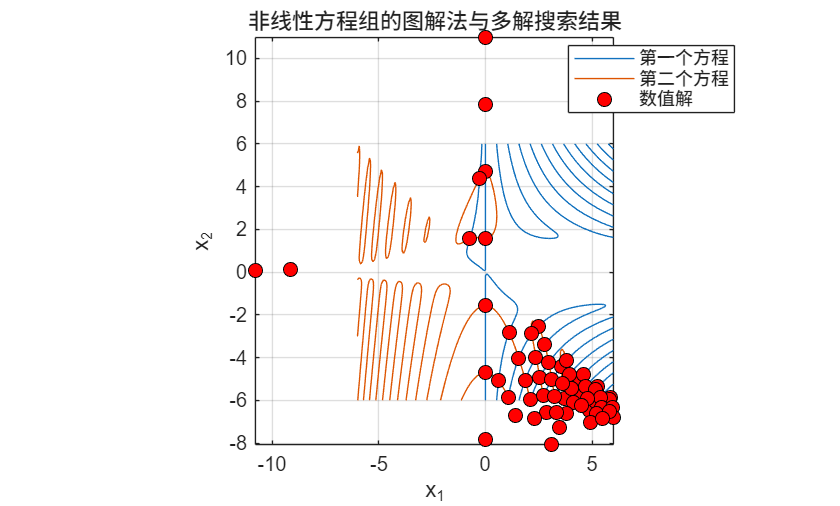


% 绘制第一个方程的零等值线
figure('Color','w')
P2_223_h1 = fimplicit(P2_223_f1,[-6,6,-6,6]);

hold on

% 绘制第二个方程的零等值线
P2_223_h2 = fimplicit(P2_223_f2,[-6,6,-6,6]);

% 标出数值搜索得到的解
if size(P2_223_VectorSolutions,3) > 0

    P2_223_rootX = squeeze(P2_223_VectorSolutions(1,1,:));
    P2_223_rootY = squeeze(P2_223_VectorSolutions(2,1,:));

    P2_223_hRoots = plot(P2_223_rootX,P2_223_rootY,'ko','MarkerFaceColor','r','MarkerSize',7);

    legend([P2_223_h1,P2_223_h2,P2_223_hRoots],'第一个方程','第二个方程','数值解','Location','best')
else
    legend([P2_223_h1,P2_223_h2],'第一个方程','第二个方程','Location','best')
end

grid on
axis equal
xlabel('x_1')
ylabel('x_2')
title('非线性方程组的图解法与多解搜索结果')